# Extracting Field Information from Holograms Example

It is easiet to run this live script  section by section one at a time

## Choose desired HDF5 file

addpath('Functions')

filename=uigetfile('*.h5');%try '20221202_09_21_23.h5';
DispComments(filename)

Measure the tilt in the reference beam by measuring the centroid of the sidelobe when the signal beam has no tilt.

area = 706.8583

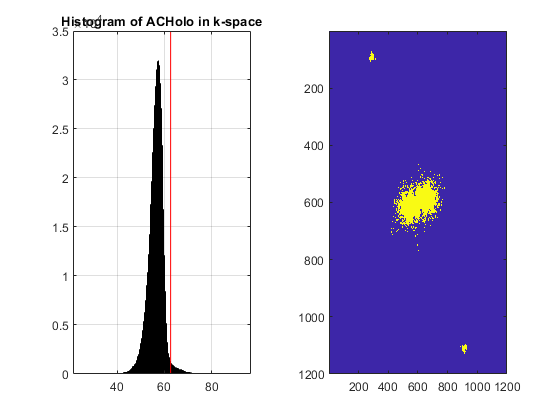

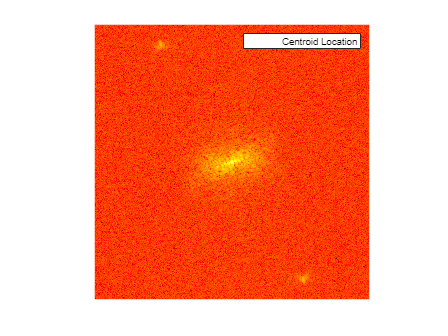

Centx = 311.3677

Centy = 510.2628

[Centx Centy]=MeasureReferenceTilt(filename)

Generate filters to avoid hard edges when taking fourier transforms and shifting with phase ramps

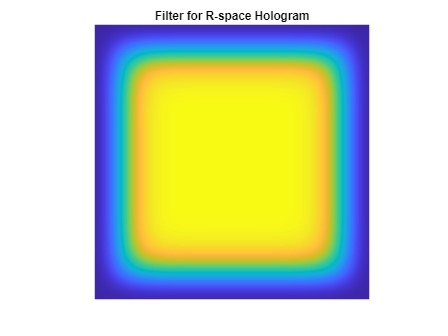

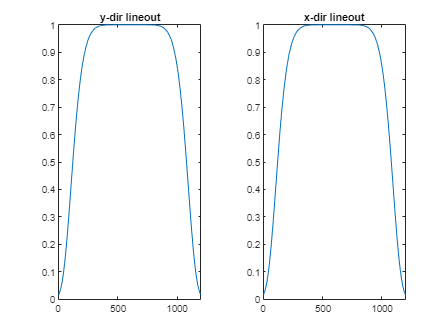

[FilterHolo ]=HoloFilterGen(filename);

Generate grids

holoinfo=h5info(filename,'/Epi/Hologram');
count=holoinfo.ChunkSize;
Epiinfo=h5info(filename,'/Epi');
datainfo=Epiinfo.Datasets.Dataspace;
datasize=datainfo.Size;
rootinfo=h5info(filename);
disp(rootinfo.Attributes.Value)   % display data comments

Muscle tissue SHG for Fourier Ptycho. Little bit hard to discern where focus is, but think it is pretty good. Fringes look great. slide position 11.39mm. delay position: 3.10mm. Doing 10x10 scan angles filling full 1/1.5 NA. This time avoiding piece of dust.



            
ps=0.5576;                        % pixel size from callibration image
Fs=1/ps;

Nx=datasize(2);
Ny=datasize(1);  
x=ps*[-Nx/2:Nx/2-1];
y=ps*[-Ny/2:Ny/2-1];
dFx=Fs/Nx;
dfxs         = dFx;%1/(N*ps);             % Fourier spacing 
fxs          = dfxs*[-Nx/2:Nx/2-1];         % 1D axis in fx
dFy=Fs/Ny;
dfys         = dFy;%1/(N*ps);             % Fourier spacing 
fys          = dfys*[-Ny/2:Ny/2-1];         % 1D axis in fy
[Xs Ys]=meshgrid(x,y);
[fxxs fyys]=meshgrid(fxs,fys);

Generate filter to select sideband according to reference tilt

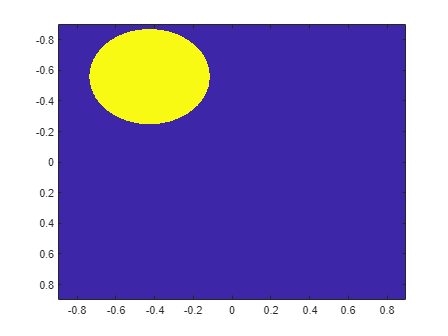

NA=.16;
lambda=1.030/2;
r=NA/lambda;
Centx=285.3309; % From previously measured reference tilt. Mistakenly used even number of points so skips over center of pupil
Centy=373.9111;
CircFilt=(fxxs+Centx*dfxs).^2+(fyys+Centy*dfys).^2<=r^2;
figure; imagesc(fxs,fys,CircFilt)

## Reconstruct Fields and store them in a matrix

Tout=GenerateTransmissionMatrix(filename,Centx,Centy,CircFilt,FilterHolo);

Muscle tissue SHG for Fourier Ptycho. Little bit hard to discern where focus is, but think it is pretty good. Fringes look great. slide position 11.39mm. delay position: 3.10mm. Doing 10x10 scan angles filling full 1/1.5 NA. This time avoiding piece of dust.
Reconstructing Fields... [++++++++++++++++++++] Finally! [12 seconds]
done!!!


**Watch video of each reconstructed spatial frequency map**

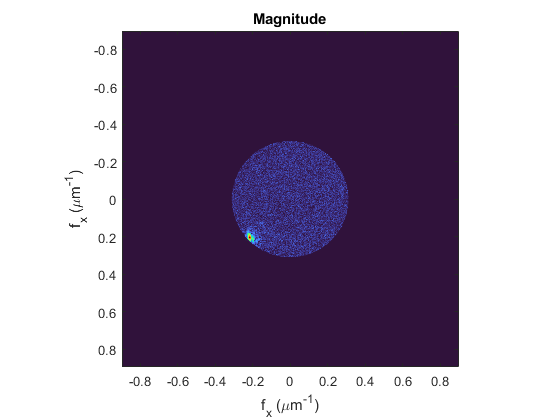


figure;
for ii=1:size(Tout,2)
    fieldk=reshape(Tout(:,ii),[datasize(1) datasize(2)]);
    imagesc(fxs,fys,abs(fieldk))
    
    axis square
    colormap Turbo
    xlabel('f_x (\mum^{-1})')
    ylabel('f_x (\mum^{-1})')
    drawnow;
end

## Reconstruct Fields and shift the spectrum to object coordinates for all angles

[Tout2 renorm]=GenerateTransmissionMatrixObjectFrame(filename,Centx,Centy,CircFilt,FilterHolo);

Muscle tissue SHG for Fourier Ptycho. Little bit hard to discern where focus is, but think it is pretty good. Fringes look great. slide position 11.39mm. delay position: 3.10mm. Doing 10x10 scan angles filling full 1/1.5 NA. This time avoiding piece of dust.
Reconstructing Fields... [++++++++++++++++++++] Finally! [11 seconds]
done!!!


%imagesc(renorm)

**Watch video of each reconstructed spatial frequency map shifted back to object coordinates**

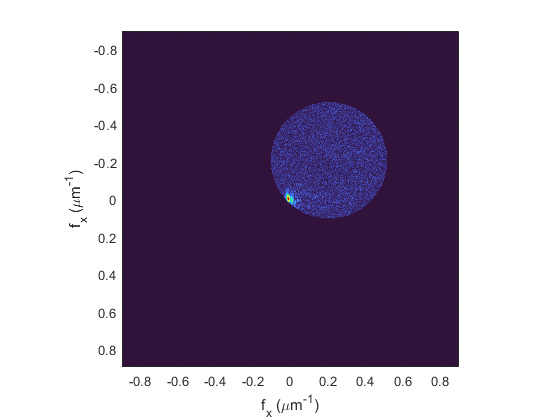

for ii=1:size(Tout,2)
    fieldk=reshape(Tout2(:,ii),[datasize(1) datasize(2)]);
    imagesc(fxs,fys,abs(fieldk))
    axis square
    colormap Turbo
    xlabel('f_x (\mum^{-1})')
    ylabel('f_x (\mum^{-1})')
    drawnow;
end